clc, clear all, close all

# Coupled Cart-Pendulum System with Torsional Springs

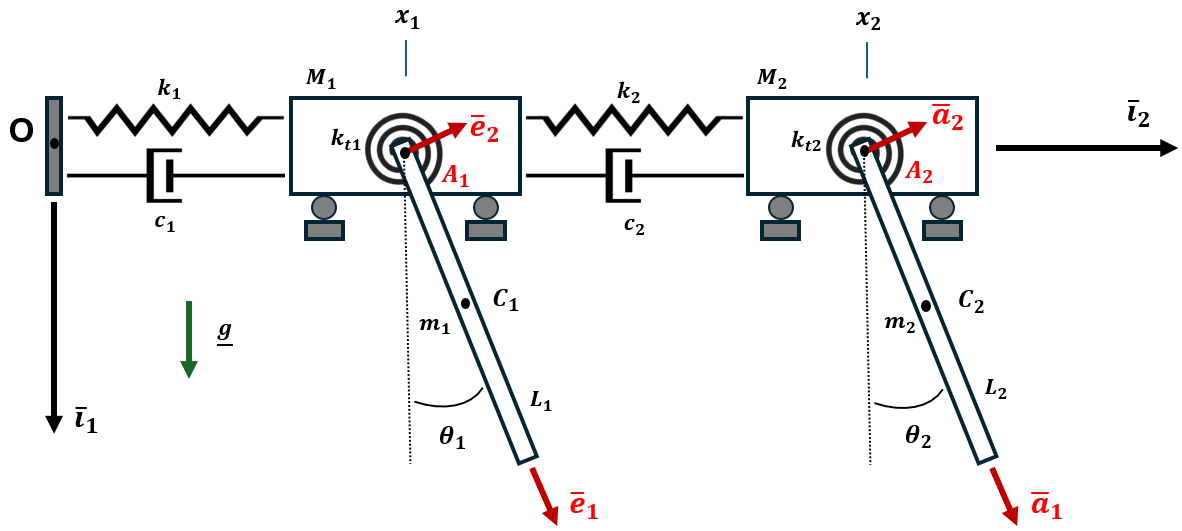

Parameters

% Masses  [Kg]
M1 = 1;
M2 = 0.8;
m1 = 0.20;
m2 = 0.15;

% Lengths  [m]
L1 = 0.40;
L2 = 0.30;

% Stiffnesses  [N/m]
k1 = 50;
k2 = 30;

% Damping coefficients  [N*s/m]
c1 = 2.0;
c2 = 1;

% Torsional Stiffnesses  [N*m/rad]
kt1 = 0.30;
kt2 = 0.20;

% Gravitational Acceleration  [m/s^2]
g = 9.81;


Initial Conditions

% Initial Positions [m] and [rad]
x1_0 = 0.08;
x2_0 = -0.04;
theta1_0 = 0.5;
theta2_0 = -0.4;

% Initial Velocities [m/s] and [rad/s]
v1_0 = 0;
v2_0 = 0;
omega1_0 = 0;
omega2_0 = 0;

y0 = [x1_0; x2_0; theta1_0; theta2_0; v1_0; v2_0; omega1_0; omega2_0];


Simulation 

tspan = [0 20]; % [s]
params = struct('M1',M1,'M2',M2,'m1',m1,'m2',m2,'L1',L1,'L2',L2,'k1',k1,'k2',k2,'c1',c1,'c2',c2,'kt1',kt1,'kt2',kt2,'g',g);


Solution of the Differential Equations using ODE45

[t, y] = ode45(@(t,y) CoupledCartPendulum(t,y,params), tspan, y0);

x1 = y(:,1);
x2 = y(:,2);
theta1 = y(:,3);
theta2 = y(:,4);
v1 = y(:,5);
v2 = y(:,6);
omega1 = y(:,7);
omega2 = y(:,8);


Total Kinetic Energy 

K = 0.5*(M1+m1)*v1.^2 + 0.5*(M2+m2)*v2.^2 + 0.5*(m1*L1^2/3)*omega1.^2 + 0.5*(m2*L2^2/3)*omega2.^2 + 0.5*m1*L1*cos(theta1).*v1.*omega1 + 0.5*m2*L2*cos(theta2).*v2.*omega2;


Total Potential Energy

Vg = m1*g*L1/2*(1-cos(theta1)) + m2*g*L2/2*(1-cos(theta2));
Ve = 0.5*k1*x1.^2 + 0.5*k2*(x2-x1).^2 + 0.5*kt1*theta1.^2 + 0.5*kt2*theta2.^2;
V  = Vg + Ve;


Total Mechanical Energy

E = K + V;


Work of Non Conservative Forces

Pd = c1*v1.^2 + c2*(v2-v1).^2;     % dissipated power
Wd = cumtrapz(t, Pd);


Principle of Energy Conservation

Ebal = E + Wd;

Results

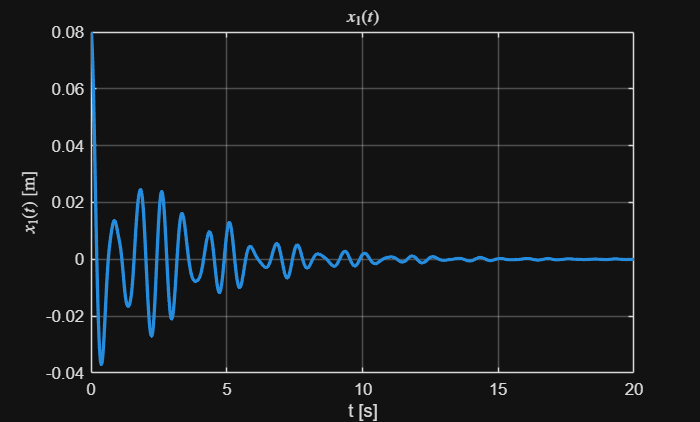

set(groot, 'DefaultLineLineWidth', 2);

figure;
plot(t,x1),title('$x_1(t)$',Interpreter='latex'),xlabel('t [s]'), ylabel('$x_1(t)$ [m]',Interpreter='latex'), grid

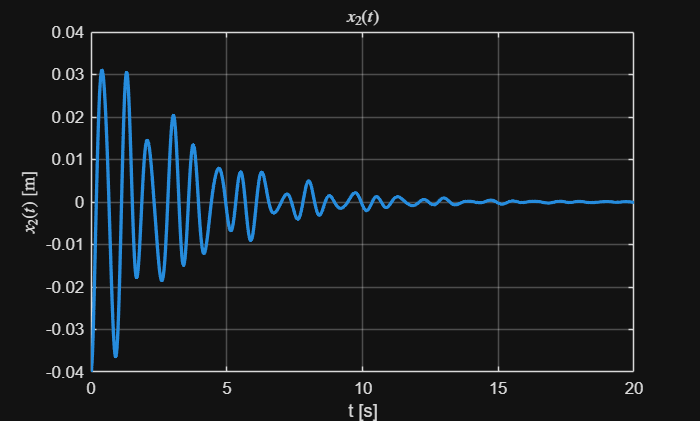

figure;
plot(t,x2),title('$x_2(t)$',Interpreter='latex'),xlabel('t [s]'),ylabel('$x_2(t)$ [m]',Interpreter='latex'),grid

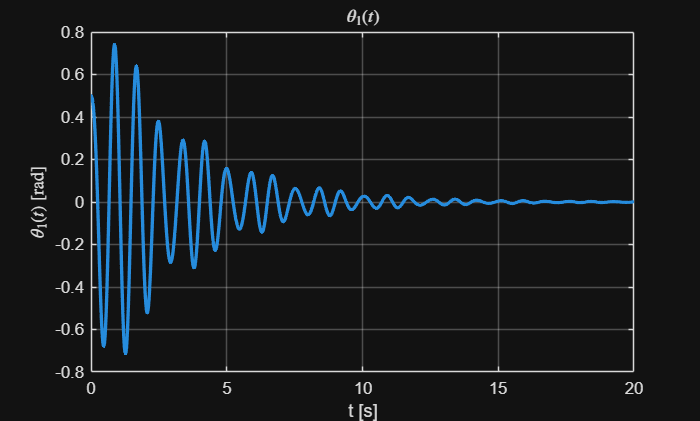


figure;
plot(t,theta1),title('$\theta_1(t)$',Interpreter='latex'),xlabel('t [s]'),ylabel('$\theta_1(t)$ [rad]',Interpreter='latex'),grid

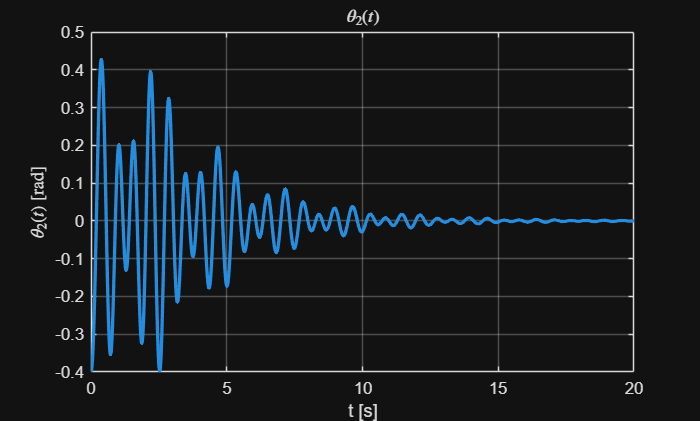

figure;
plot(t,theta2),title('$\theta_2(t)$',Interpreter='latex'),xlabel('t [s]'),ylabel('$\theta_2(t)$ [rad]',Interpreter='latex'),grid

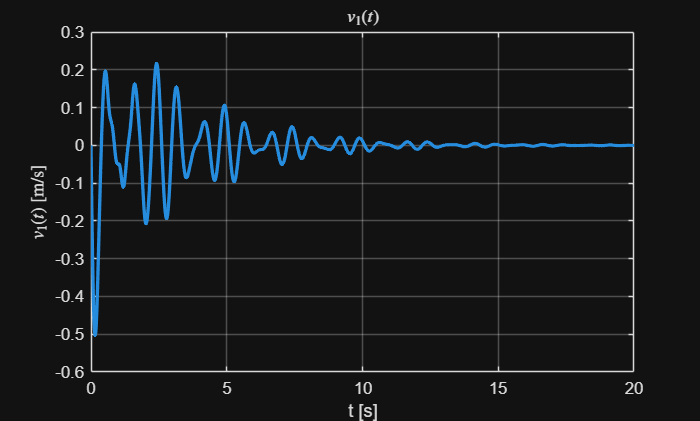


figure;
plot(t,v1),title('$v_1(t)$',Interpreter='latex'),xlabel('t [s]'),ylabel('$v_1(t)$ [m/s]',Interpreter='latex'),grid

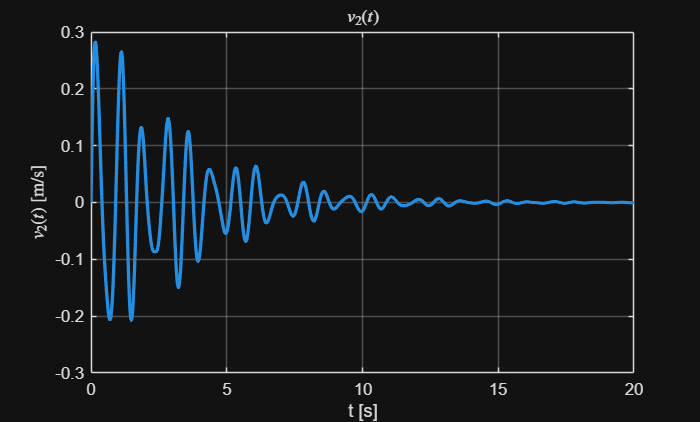


figure;
plot(t,v2),title('$v_2(t)$',Interpreter='latex'),xlabel('t [s]'),ylabel('$v_2(t)$ [m/s]',Interpreter='latex'),grid

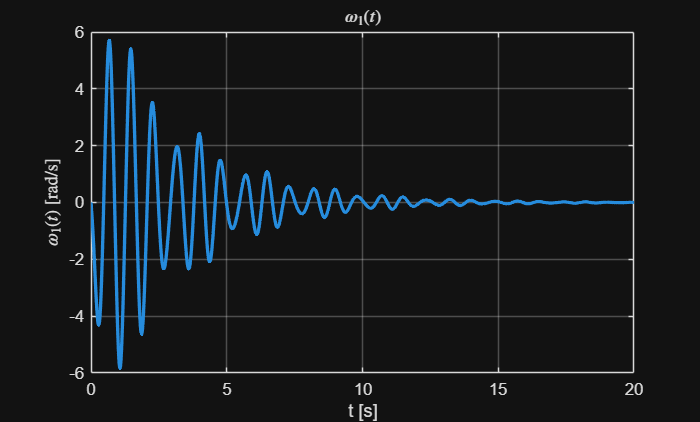


figure;
plot(t,omega1),title('$\omega_1(t)$',Interpreter='latex'),xlabel('t [s]'),ylabel('$\omega_1(t)$ [rad/s]',Interpreter='latex'),grid

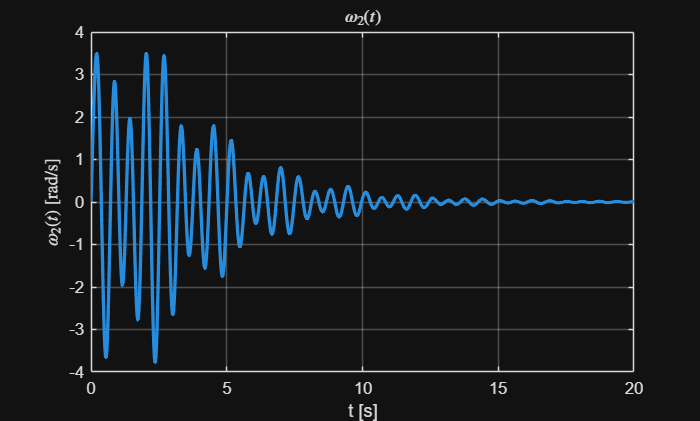


figure;
plot(t,omega2),title('$\omega_2(t)$',Interpreter='latex'),xlabel('t [s]'),ylabel('$\omega_2(t)$ [rad/s]',Interpreter='latex'),grid

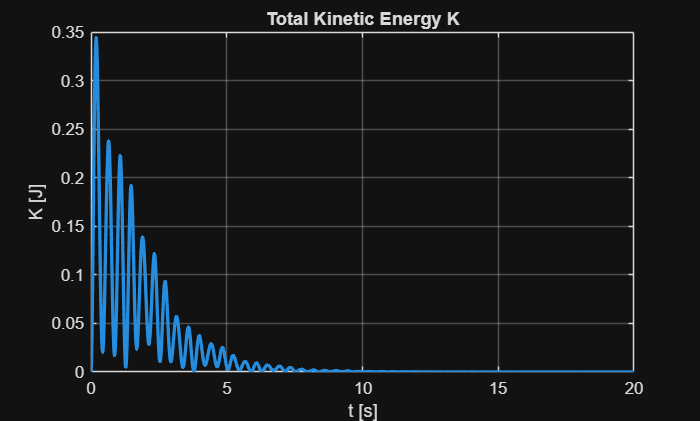


figure;
plot(t,K), title('Total Kinetic Energy K'),xlabel('t [s]'),ylabel('K [J]'),grid

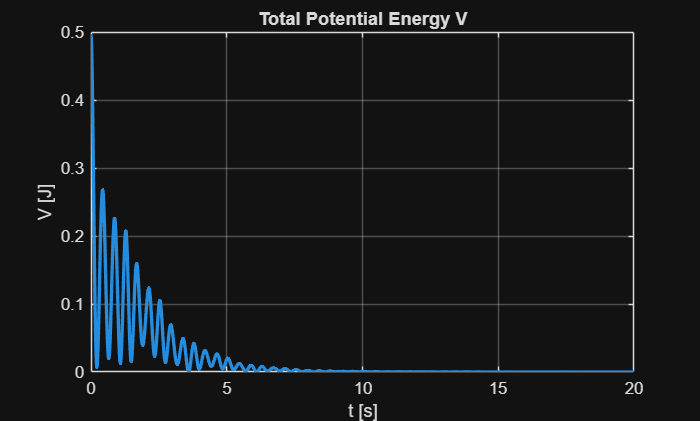


figure;
plot(t,V),title('Total Potential Energy V'),xlabel('t [s]'),ylabel('V [J]'),grid

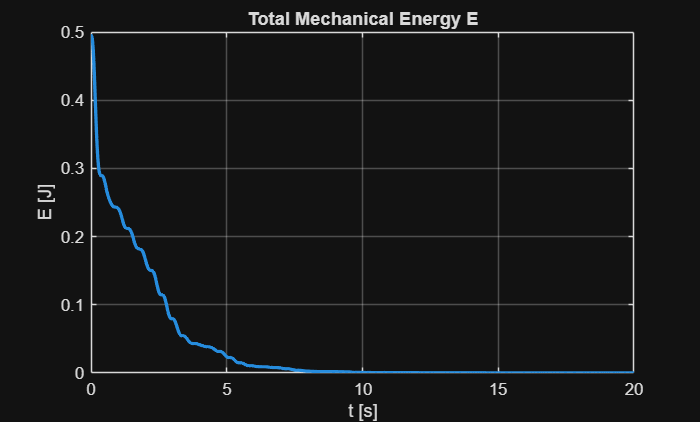


figure;
plot(t,E),title('Total Mechanical Energy E'),xlabel('t [s]'),ylabel('E [J]'),grid

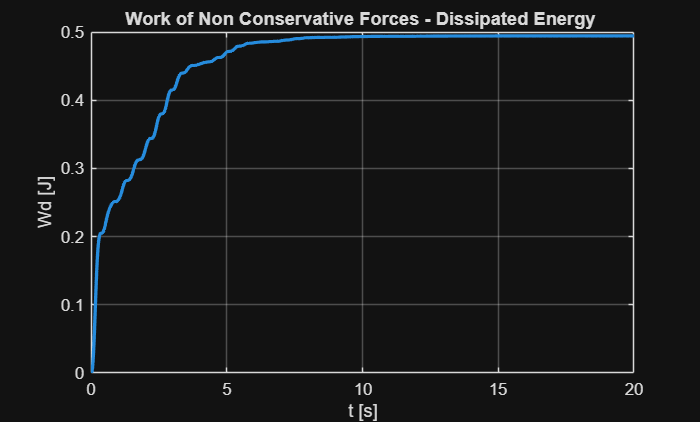


figure;
plot(t,Wd),title('Work of Non Conservative Forces - Dissipated Energy '),xlabel('t [s]'),ylabel('Wd [J]'),grid

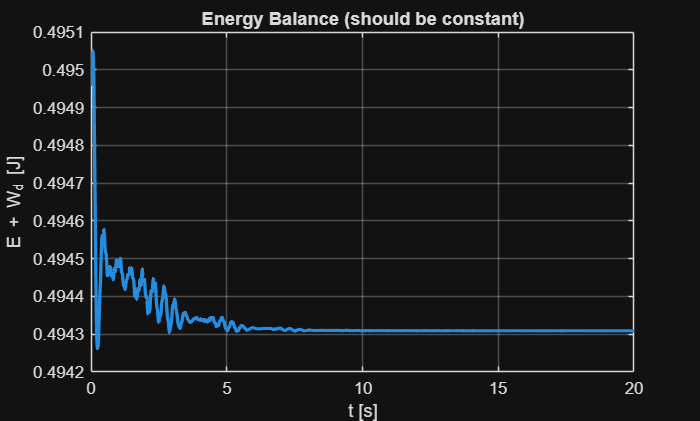


figure;
plot(t,Ebal),title('Energy Balance (should be constant)'),xlabel('t [s]'),ylabel('E + W_d [J]'),grid

Differential Equations: Function

function dydt = CoupledCartPendulum(~, y, p)

% State Variables
x1 = y(1); 
x2 = y(2); 
th1 = y(3); 
th2 = y(4);
v1 = y(5);
v2 = y(6); 
w1 = y(7); 
w2  = y(8);

% Coefficients of the DE
S1 = sin(th1); C1 = cos(th1);
S2 = sin(th2); C2 = cos(th2);

D1 = p.M1 + p.m1 - 0.75*p.m1*C1^2;
D2 = p.M2 + p.m2 - 0.75*p.m2*C2^2;

G1 = p.m1*p.g*p.L1/2*S1 + p.kt1*th1;
G2 = p.m2*p.g*p.L2/2*S2 + p.kt2*th2;

P1 = p.m1*p.L1/2*S1*w1^2 - p.k1*x1 - p.c1*v1 - p.k2*(x1-x2) - p.c2*(v1-v2);
P2 = p.m2*p.L2/2*S2*w2^2 - p.k2*(x2-x1) - p.c2*(v2-v1);

% Time Derivatives of the State Variables
a1 = (P1 + 3*C1/(2*p.L1)*G1) / D1;
a2 = (P2 + 3*C2/(2*p.L2)*G2) / D2;
b1 = (-3*(p.M1+p.m1)/(p.m1*p.L1^2)*G1 - 3*C1/(2*p.L1)*P1) / D1;
b2 = (-3*(p.M2+p.m2)/(p.m2*p.L2^2)*G2 - 3*C2/(2*p.L2)*P2) / D2;

dydt = [v1; v2; w1; w2; a1; a2; b1; b2];

end
